%let each unit be 1cm
%trying to achieve forward kinematics: 
% the position of the tool tip in terms of the base reference frame 
% (gives the actual position) then can determine the desired tool tip 
% position (relative to the heart)

% HRF = heart reference frame
% VRF = fixed point where the voice coil actuator sits inside the device (non-actuating part)
% TRF = tool-tip reference frame (actuating)
% BRF = base of device

unit vectors for reference frame 1

% Define the plane
[X, Y] = meshgrid(0:40.2, 0:80.4);%should be 40.2 & 80.4
Z = zeros(size(X));% Z is constant for a flat plane

% Plot the plane
surf(X, Y, Z, 'FaceAlpha', 0.5);
hold on;

BRF_pt = [40.2-13.5, 21.0, 0];

DH PARAMETERS--> Calculate transformation matrices

l01A=26.1;d01=0;l01B=0;l45A=10;1;l45B=11.5;l56A=1;d56potentiometer=2;l56B=1;
%gyro
theta2_yaw=180*pi/180;
theta3_pitch=0;
theta4_roll=50*pi/180;
%           a       α       d                           θ
dhparams = [0   	0	    l01A+d01+l01B               0
            0	    pi/2    0                           theta2_yaw
            0	    pi/2    0                           theta3_pitch
            0	    0       0                           theta4_roll
            l45A    0       l45B                        0];
%            0	    0	    l56A+d56potentiometer+l56B  0];

%%%%% practice params %%%%%%
% dhparams = [10 0 0  pi/2;
%             10 0 0 -pi/2;
%             10 0 0 -pi/2;];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%hold the joint matrices
individualJT= cell(1,3);

%cycle through joints & plot them
n = size(dhparams, 1);
for i = 1:n 
    T= JointTransformation(dhparams(i,1), dhparams(i,2), dhparams(i,3), dhparams(i,4));
    individualJT{i}=T;
    if i==1
        totaltransformation=T;
    else
        totaltransformation=totaltransformation*T;
    end
joint_pt = [BRF_pt(1)+totaltransformation(1,4),BRF_pt(2)+totaltransformation(2,4),BRF_pt(3)+totaltransformation(3,4)];
%unit vectors are the columns of the rotational matrix
% Plot the unit vectors
plotunitvector(joint_pt,totaltransformation(1:3,1),totaltransformation(1:3,2),totaltransformation(1:3,3));


end

totaltransformation

totaltransformation =    -0.6428    0.7660    0.0000   -6.4279
    0.7660    0.6428    0.0000    7.6604
    0.0000    0.0000   -1.0000   14.6000
         0         0         0    1.0000


PLOT points

% Define the BRF point on the plane

% Create unit vectors
u = [1, 0, 0]; % Unit vector in x-direction
v = [0, 1, 0]; % Unit vector in y-direction
w = [0, 0, 1]; % Unit vector in z-direction
% Plot the unit vectors
plotunitvector(BRF_pt,u,v,w)

% %tool tip reference frame (position of BRF + distance from brf to tool tip)
% tooltip_pt = [BRF_pt(1)+totaltransformation(1,4),BRF_pt(2)+totaltransformation(2,4),BRF_pt(3)+totaltransformation(3,4)]
% %unit vectors are the column of the rotational matrix
% u_tooltip=totaltransformation(1:3,1)%1:3 selects first 3 rows
% v_tooltip=totaltransformation(1:3,2)
% w_tooltip=totaltransformation(1:3,3)
% % Plot the unit vectors
% plotunitvector(tooltip_pt,u_tooltip,v_tooltip,w_tooltip)



display

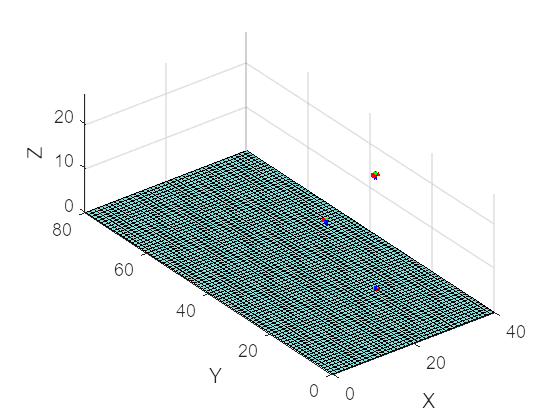

% Set axis properties
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

functions 

function T = JointTransformation(a, alpha, d, theta)
    T = [cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha)  a*cos(theta)
         sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta)
         0          sin(alpha)            cos(alpha)             d
         0          0                     0                      1];
end
% JointTransformation(dhparams(i,1), dhparams(i,2), dhparams(i,3), dhparams(i,4));

function P = plotunitvector(pt,u,v,w)
    quiver3(pt(1), pt(2), pt(3), u(1), u(2), u(3), 'r', 'LineWidth', 2);
    quiver3(pt(1), pt(2), pt(3), v(1), v(2), v(3), 'g', 'LineWidth', 2);
    quiver3(pt(1), pt(2), pt(3), w(1), w(2), w(3), 'b', 'LineWidth', 2);
end